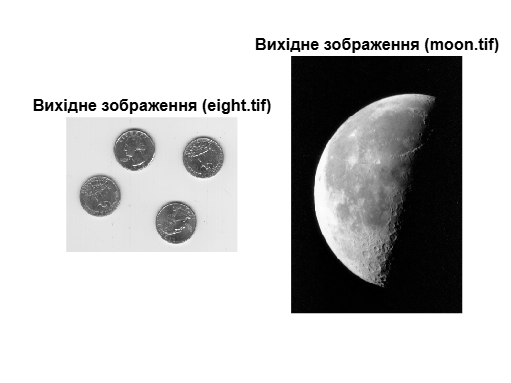

clear; close all; clc;

I1 = imread('eight.tif');
I2 = imread('moon.tif');

figure;
subplot(1,2,1), imshow(I1), title('Вихідне зображення (eight.tif)');
subplot(1,2,2), imshow(I2), title('Вихідне зображення (moon.tif)');

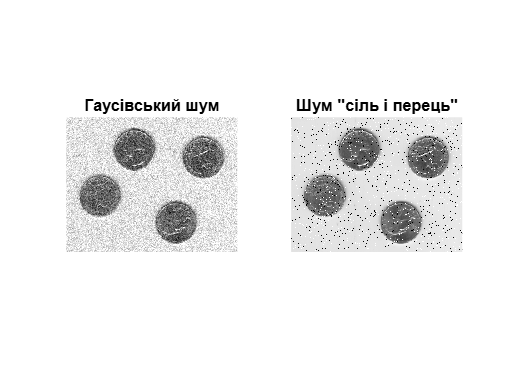


% Гаусівський шум (параметри: середнє 0, дисперсія 0.01)
J_gaussian = imnoise(I1, 'gaussian', 0, 0.01);

% Імпульсний шум (щільність 0.05)
J_saltpepper = imnoise(I1, 'salt & pepper', 0.05);

figure;
subplot(1,2,1), imshow(J_gaussian), title('Гаусівський шум');
subplot(1,2,2), imshow(J_saltpepper), title('Шум "сіль і перець"');

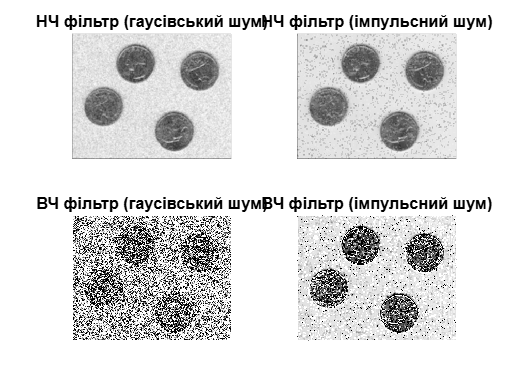


% Низькочастотний фільтр (середнє вікно 3x3)
h_low = ones(3,3) / 9;
filtered_low_gaussian = imfilter(J_gaussian, h_low);
filtered_low_saltpepper = imfilter(J_saltpepper, h_low);

% Високочастотний фільтр (маска для підкреслення країв)
h_high = [-1 -1 -1; -1 9 -1; -1 -1 -1];
filtered_high_gaussian = imfilter(J_gaussian, h_high);
filtered_high_saltpepper = imfilter(J_saltpepper, h_high);

figure;
subplot(2,2,1), imshow(filtered_low_gaussian), title('НЧ фільтр (гаусівський шум)');
subplot(2,2,2), imshow(filtered_low_saltpepper), title('НЧ фільтр (імпульсний шум)');
subplot(2,2,3), imshow(filtered_high_gaussian), title('ВЧ фільтр (гаусівський шум)');
subplot(2,2,4), imshow(filtered_high_saltpepper), title('ВЧ фільтр (імпульсний шум)');

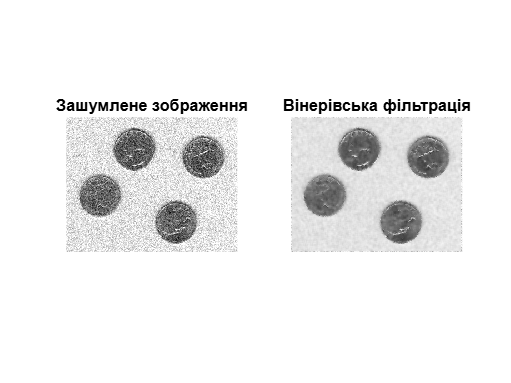


% Вінерівська фільтрація для гаусівського шуму
K_wiener = wiener2(J_gaussian, [5 5]);

figure;
subplot(1,2,1), imshow(J_gaussian), title('Зашумлене зображення');
subplot(1,2,2), imshow(K_wiener), title('Вінерівська фільтрація');

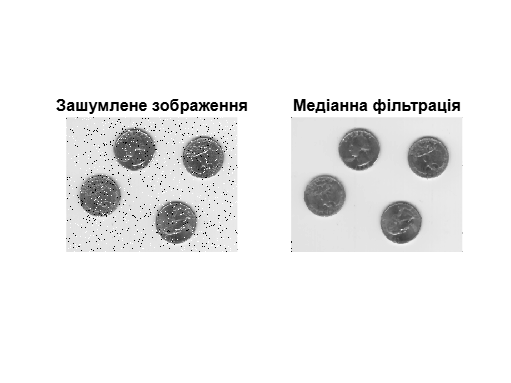


% Медіанний фільтр для імпульсного шуму
K_median = medfilt2(J_saltpepper, [3 3]);

figure;
subplot(1,2,1), imshow(J_saltpepper), title('Зашумлене зображення');
subplot(1,2,2), imshow(K_median), title('Медіанна фільтрація');


% Медіанний фільтр для імпульсного шуму
K_median = medfilt2(J_saltpepper, [3 3]);

figure;
subplot(1,2,1), imshow(J_saltpepper), title('Зашумлене зображення');
subplot(1,2,2), imshow(K_median), title('Медіанна фільтрація');